clear;      % Removes all variables from the workspace
clc;        % Clears the Command Window
close all;  % Closes any hidden or external figure windows

raw_data = load("identification_data\rod_2_identification\matlab.mat");

% Unpack the loaded data into struct
angles = 15:15:120;

for i = 1:length(angles)
    var_name = sprintf('theta_2_%d_degrees', angles(i));
    data = raw_data.(var_name);

    expData(i).t = data.Time;
    expData(i).y_raw = data.Data;
    expData(i).u = zeros(size(data.Time));
    expData(i).initial_angle = angles(i);
end

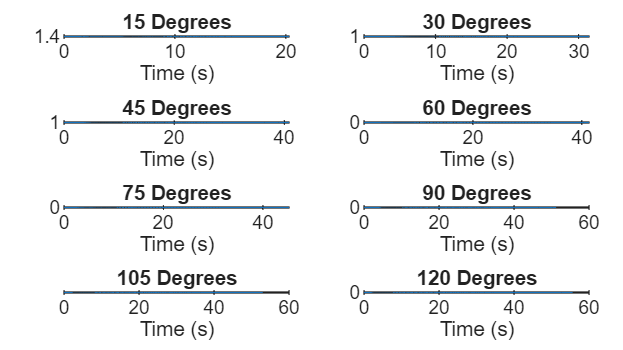

% Plotting raw data in time domain
figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

for i = 1:length(angles)
    nexttile;
    plot(expData(i).t, expData(i).y_raw, "DisplayName", "Raw Data");
    title(sprintf('%d Degrees', angles(i)));
    ylabel("Angle (rads)");
    xlabel("Time (s)");
end

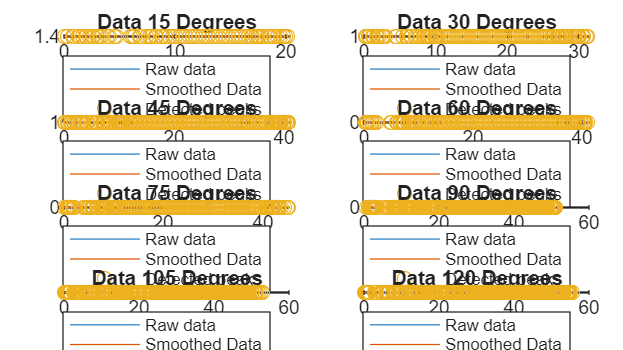

% Plot data with peak detection to truncate usefull data
figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for i = 1:length(angles)

    Ts = expData(i).t(2) - expData(i).t(1);
    fs = 1/Ts;

    % Filter out noise for peak detection
    fc = 5;     % Cut off frequency
    [b, a] = butter(3, fc/(fs/2), 'low');
    
    expData(i).y_smooth = filtfilt(b, a, expData(i).y_raw);

    % Find peaks
    minDist = round(0.3 * fs);
    [pMax, locMax] = findpeaks(expData(i).y_smooth, 'MinPeakDistance', minDist);
    [pMin, locMin] = findpeaks(-expData(i).y_smooth, 'MinPeakDistance', minDist);
    peak_indices = sort([locMax; locMin]);
    
    % Plot data with detected peaks
    nexttile;
    plot(expData(i).t, expData(i).y_raw, 'DisplayName', 'Raw data');
    hold on;
    plot(expData(i).t, expData(i).y_smooth, 'DisplayName', 'Smoothed Data');
    plot(expData(i).t(peak_indices), expData(i).y_smooth(peak_indices), 'o', 'DisplayName', 'Detected peaks');
    
    legend;
    title(sprintf('Data %d Degrees', angles(i)));
    xlabel('Time (s)');
    ylabel('Angle (rad)');
end

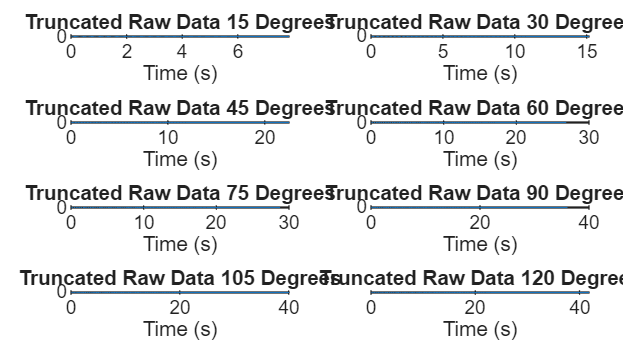

% Set indices for truncated data
expData(1).start_index = 919;
expData(1).end_index = 1703;

expData(2).start_index = 1078;
expData(2).end_index = 2594;

expData(3).start_index = 1089;
expData(3).end_index = 3339;

expData(4).start_index = 955;
expData(4).end_index = 3643;

expData(5).start_index = 1091;
expData(5).end_index = 3969;

expData(6).start_index = 1051;
expData(6).end_index = 4656;

expData(7).start_index = 851;
expData(7).end_index = 4857;

expData(8).start_index = 802;
expData(8).end_index = 4984;

for i = 1:length(angles)
    expData(i).y_id = expData(i).y_raw(expData(i).start_index:expData(i).end_index);
    expData(i).y_id = expData(i).y_id - mean(expData(i).y_raw(expData(i).end_index + 1:end));
    expData(i).t_id = expData(i).t(expData(i).start_index:expData(i).end_index);
    expData(i).t_id = expData(i).t_id - expData(i).t_id(1);
    expData(i).u_id = zeros(length(expData(i).y_id), 1);
end

% Plot truncated data time and frequency domain
figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for i = 1:length(angles)

    % Plot data with detected peaks
    nexttile;
    plot(expData(i).t_id, expData(i).y_id);

    title(sprintf('Truncated Raw Data %d Degrees', angles(i)));
    xlabel('Time (s)');
    ylabel('Angle (rad)');
end

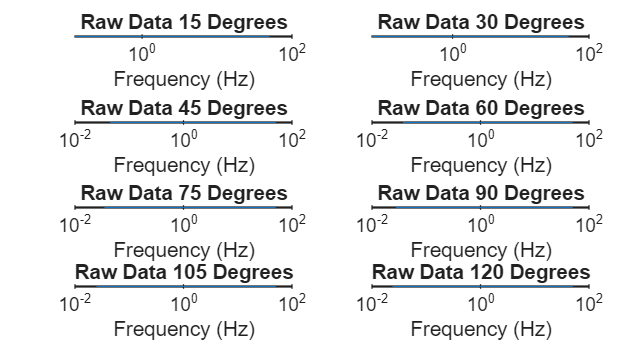

figure('Units', 'normalized', 'Position', [0, 0, 1, 1]);
tiledlayout(4, 2, 'TileSpacing', 'compact', 'Padding', 'compact');
for i = 1:length(angles)

    % Calc sampling period and frequency
    Ts = expData(i).t(2) - expData(i).t(1);
    fs = 1/Ts;

    data_length = length(expData(i).y_id);

    % Compute the FFT
    y_fft = fft(expData(i).y_id);
    
    % Compute the two-sided spectrum P2
    P2 = abs(y_fft / data_length);
    
    % Compute the single-sided spectrum P1 based on P2
    P1 = P2(1:floor(data_length/2)+1);
    
    % Multiply by 2 to conserve energy (excluding DC and Nyquist frequencies)
    P1(2:end-1) = 2 * P1(2:end-1);
    
    % Define the frequency domain f (up to the Nyquist frequency)
    f = fs * (0:floor(data_length/2)) / data_length;
    
    nexttile;
    plot(f, P1, 'LineWidth', 1.2);
    
    title(sprintf('Raw Data %d Degrees', angles(i)));
    xlabel("Frequency (Hz)");
    ylabel("Amplitude");
    xscale('log')
end


Initial Coulomb parameter guesses:


p_b2_init  = 0.197115  [1/s]


p_g2_init  = 105.948  [1/s^2]


p_c2_init  = 0.52974  [rad/s^2]


eps_v_init = 0.03  [rad/s]



    ExperimentIndex    DominantFrequency_Hz    p_b2_guess    p_g2_guess    p_c2_guess    eps_v_guess
    _______________    ____________________    __________    __________    __________    ___________

           1                  1.6561            0.56926        108.35       0.54175       0.019404  
           3                  1.6437            0.21831        106.67       0.53337           0.03  
           5                  1.6325            0.17592        105.22       0.52611           0.03  
           7                  1.4974            0.13693        88.521       0.44261           0.03  



Estimated Coulomb-viscous model:



estimated_model_coulomb =

Continuous-time nonlinear grey-box model defined by 'pendulum_rod_2_model_coulomb' (MATLAB file):

   dx/dt = F(t, x(t), u(t), p1, ..., p4)
    y(t) = H(t, x(t), u(t), p1, ..., p4) + e(t)

 with 1 input(s), 2 state(s), 1 output(s), and 3 free parameter(s) (out of 4).

 Inputs:
    u(1)  u(t) [-]
 States:                       Initial value
    x(1)  theta(t) [rad]         xinit@exp1   0.245596   (fixed) in [-Inf, Inf]
                                 xinit@exp2   0.763433   (fixed) in [-Inf, Inf]
                                 xinit@exp1   0.332351   (fixed) in [-Inf, Inf]
                                 xinit@exp2   0.686112   (fixed) in [-Inf, Inf]
    x(2)  theta_dot(t) [rad/s]   xinit@exp1   0.332351   (estimated) in [-Inf, Inf]
                                 xinit@exp2   0.686112   (estimated) in [-Inf, Inf]
                                 xinit@exp3   0.947384   (estimated) in [-Inf, Inf]
                                 xinit@exp4   -0.70266   (


Estimated Coulomb-viscous parameters:


p_b2  = 0.067139266  [1/s]


p_g2  = 112.01559  [1/s^2]


p_c2  = 0.24875764  [rad/s^2]


eps_v = 0.03  [rad/s]


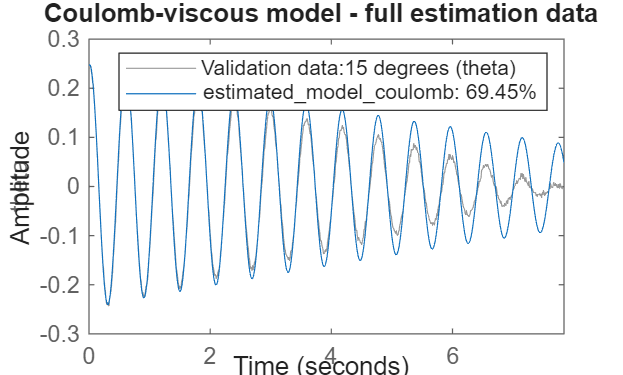

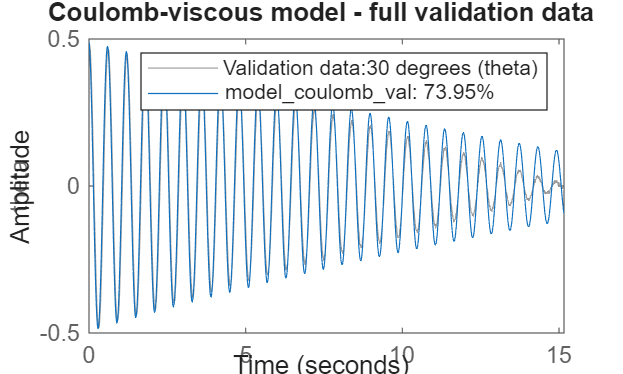

Experiment 15 degrees: tail starts at 0.020 s, index 3, duration 7.820 s
Experiment 30 degrees: tail starts at 7.200 s, index 721, duration 7.960 s
Experiment 45 degrees: tail starts at 14.200 s, index 1421, duration 8.300 s
Experiment 60 degrees: tail starts at 18.260 s, index 1827, duration 8.620 s
Experiment 75 degrees: tail starts at 20.770 s, index 2078, duration 8.010 s
Experiment 90 degrees: tail starts at 28.040 s, index 2805, duration 8.010 s
Experiment 105 degrees: tail starts at 30.900 s, index 3091, duration 9.160 s
Experiment 120 degrees: tail starts at 32.860 s, index 3287, duration 8.960 s


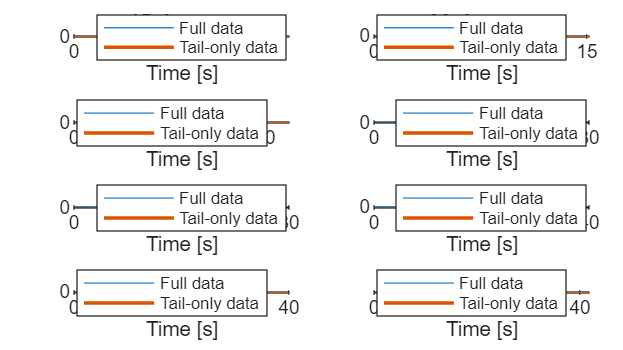


Base initial low-velocity damping parameter guesses from Coulomb result:


p_b2     = 0.067139266  [1/s]
p_g2     = 112.01559  [1/s^2]
p_c2     = 0.24875764  [rad/s^2]
p_b_low  = 0.13427853  [1/s]
v_b      = 0.15  [rad/s]
eps_v    = 0.02  [rad/s]



Running 30 multi-start tail-only fits...


Start 01/30: loss = 2.89962e-05, p_b_low = 0.242508, v_b = 0.506609
Start 02/30: loss = 2.89991e-05, p_b_low = 0.219444, v_b = 0.496953
Start 03/30: loss = 2.89973e-05, p_b_low = 0.247899, v_b = 0.490792
Start 04/30: loss = 2.89959e-05, p_b_low = 0.240371, v_b = 0.514253
Start 05/30: loss = 2.89958e-05, p_b_low = 0.244986, v_b = 0.514232
Start 06/30: loss = 2.91241e-05, p_b_low = 0.0368161, v_b = 0.0589698


Start 07/30 failed: Initial value of parameter 3 is outside its bounds.
Value = 6.31773, Minimum = 0, Maximum = 4.97515


Start 08/30: loss = 2.91118e-05, p_b_low = 0.000631761, v_b = 0.00500002
Start 09/30: loss = 2.91111e-05, p_b_low = 3.14622e-06, v_b = 0.289441
Start 10/30: loss = 2.89971e-05, p_b_low = 0.239141, v_b = 0.496929
Start 11/30: loss = 2.89978e-05, p_b_low = 0.229513, v_b = 0.498716
Start 12/30: loss = 2.89959e-05, p_b_low = 0.24366, v_b = 0.514823
Start 13/30: loss = 2.89958e-05, p_b_low = 0.244083, v_b = 0.513552
Start 14/30: loss = 2.89967e-05, p_b_low = 0.240592, v_b = 0.500113
Start 15/30: loss = 2.91135e-05, p_b_low = 0.0296774, v_b = 0.0115907
Start 16/30: loss = 2.89997e-05, p_b_low = 0.235904, v_b = 0.523044
Start 17/30: loss = 2.89984e-05, p_b_low = 0.223663, v_b = 0.499375
Start 18/30: loss = 2.89974e-05, p_b_low = 0.235047, v_b = 0.497079
Start 19/30: loss = 2.89974e-05, p_b_low = 0.231546, v_b = 0.501192
Start 20/30: loss = 2.91108e-05, p_b_low = 2.41624e-05, v_b = 0.00500018
Start 21/30: loss = 2.89963e-05, p_b_low = 0.238481, v_b = 0.508724
Start 22/30: loss = 2.89961e-05, p

Start 29/30 failed: Initial value of parameter 3 is outside its bounds.
Value = 7.72227, Minimum = 0, Maximum = 4.97515


Start 30/30: loss = 2.89969e-05, p_b_low = 0.23398, v_b = 0.504047


Multi-start tail-only results:


    StartNumber       Loss          p_b2        p_g2      p_c2       p_b_low         v_b       Converged
    ___________    __________    __________    ______    _______    __________    _________    _________

         5         2.8996e-05      0.021531    112.02    0.46408       0.24499      0.51423      true   
        13         2.8996e-05      0.021377    112.02    0.46437       0.24408      0.51355      true   
        26         2.8996e-05      0.021271    112.02    0.46461       0.24499      0.51132      true   
        12         2.8996e-05      0.021581    112.02    0.46399       0.24366      0.51482      true   
         4         2.8996e-05       0.02111    112.02    0.46486       0.24037      0.51425      


Best tail-only low-velocity damping parameters:


p_b2     = 0.021530705  [1/s]
p_g2     = 112.01559  [1/s^2]
p_c2     = 0.46408187  [rad/s^2]
p_b_low  = 0.24498584  [1/s]
v_b      = 0.51423244  [rad/s]
eps_v    = 0.02  [rad/s]


Best tail-only low-velocity damping model:



bestTailModel =

Continuous-time nonlinear grey-box model defined by 'pendulum_rod_2_model_lowvel_damping' (MATLAB file):

   dx/dt = F(t, x(t), u(t), p1, ..., p6)
    y(t) = H(t, x(t), u(t), p1, ..., p6) + e(t)

 with 1 input(s), 2 state(s), 1 output(s), and 4 free parameter(s) (out of 6).

 Inputs:
    u(1)  u(t) [-]
 States:                       Initial value
    x(1)  theta(t) [rad]         xinit@exp1    0.245596   (fixed) in [-Inf, Inf]
                                 xinit@exp2   -0.263481   (fixed) in [-Inf, Inf]
                                 xinit@exp1   -0.125955   (fixed) in [-Inf, Inf]
                                 xinit@exp2   -0.212464   (fixed) in [-Inf, Inf]
    x(2)  theta_dot(t) [rad/s]   xinit@exp1   -0.125955   (estimated) in [-Inf, Inf]
                                 xinit@exp2   -0.212464   (estimated) in [-Inf, Inf]
                                 xinit@exp3    0.104828   (estimated) in [-Inf, Inf]
                                 xinit@exp4    0.20309

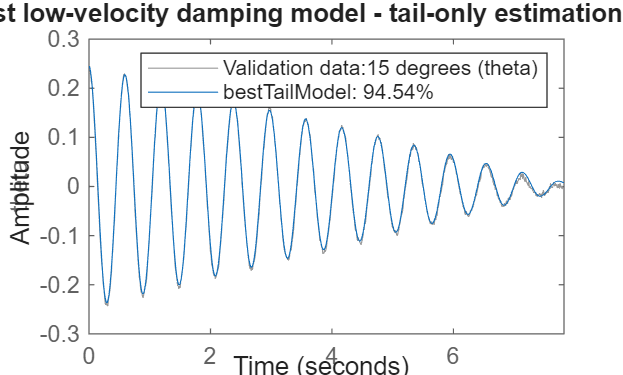

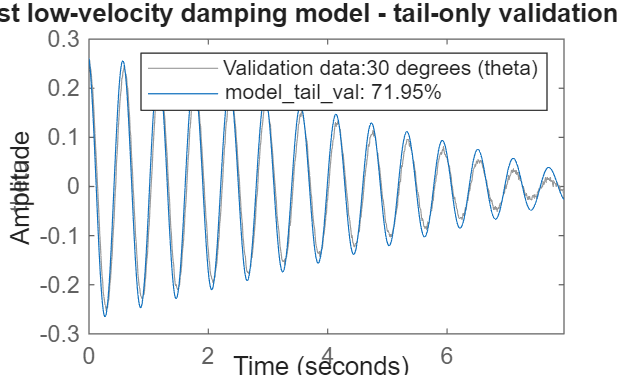

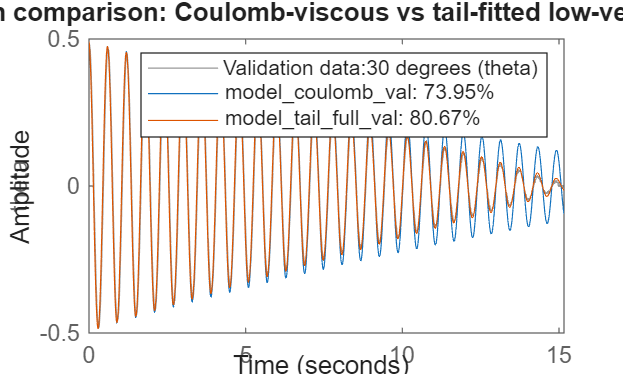

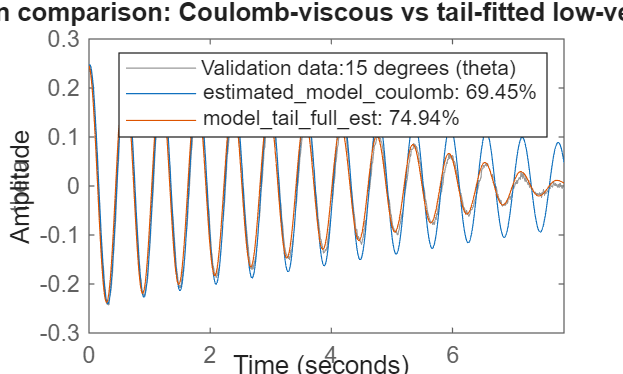

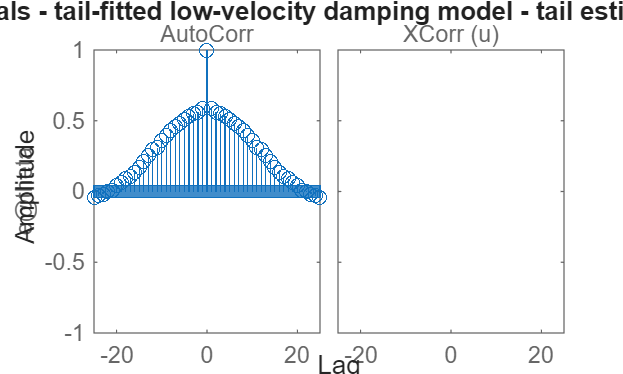

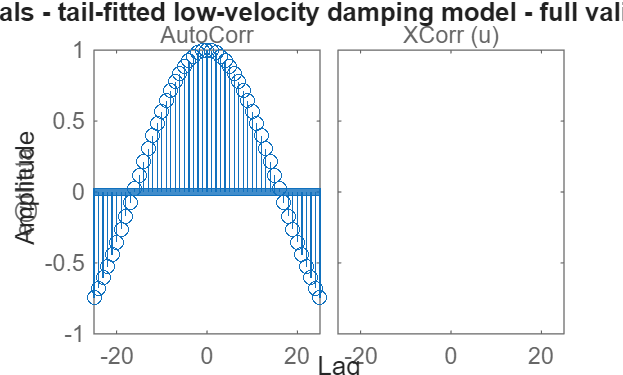

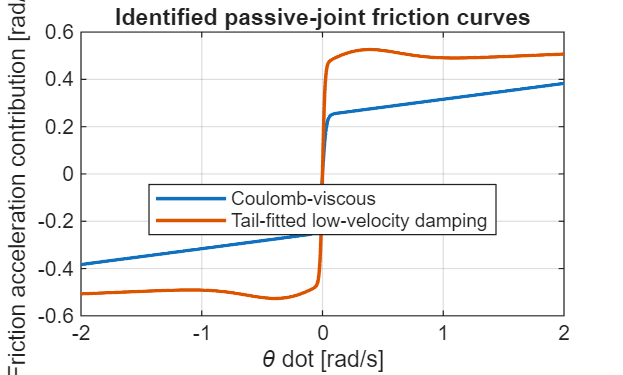

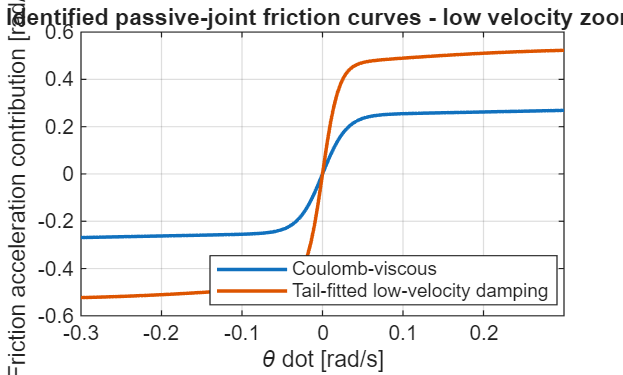

%% Identification setup - simplified Coulomb model + full low-velocity damping model

% Estimation and validation experiments
idxEst = [1 3 5 7];  % 15, 45, 75, 105 degrees
idxVal = [2 4 6 8];  % 30, 60, 90, 120 degrees

rng(1);  % Repeatable multistart results

% Sampling time
Ts = expData(1).t_id(2) - expData(1).t_id(1);

for i = 1:numel(expData)
    Ts_i = expData(i).t_id(2) - expData(i).t_id(1);

    if abs(Ts_i - Ts) > 1e-9
        error('Experiment %d has a different sampling time.', i);
    end
end

% General settings
Ts_model = 0;          % Continuous-time grey-box model
Order = [1 1 2];       % [number of outputs, number of inputs, number of states]

% Tail-data settings for fitting the low-velocity damping model
tailAmplitudeThreshold = 0.25;   % rad
minTailDuration = 3.0;           % seconds
numMultiStarts = 30;

%% Build full iddata objects

z = buildPendulumIdData(expData, Ts);

z_est = merge(z{idxEst});
z_val = merge(z{idxVal});

z_est.Name = 'Full estimation data';
z_val.Name = 'Full validation data';

%% Estimate Coulomb-viscous model on full data

FileNameCoulomb = 'pendulum_rod_2_model_coulomb';

if isempty(which(FileNameCoulomb))
    error('MATLAB cannot find "%s.m". Make sure it is on the MATLAB path.', FileNameCoulomb);
end

% Initial parameter guess:
% p(1) = p_b2
% p(2) = p_g2
% p(3) = p_c2
% p(4) = eps_v
p0_coulomb = estimatePassivePendulumInitialGuessCoulomb(expData, idxEst, Ts);

x0_est = estimateInitialStates(expData, idxEst);

% Estimate p_b2, p_g2 and p_c2.
% Keep eps_v fixed because it is mainly a numerical smoothing parameter.
parameterFixedCoulomb = [
    false   % p_b2
    false   % p_g2
    false   % p_c2
    true    % eps_v
];

model_coulomb = createRod2GreyBoxModelCoulomb( ...
    FileNameCoulomb, Order, p0_coulomb, x0_est, Ts_model, ...
    parameterFixedCoulomb, ...
    true);  % estimate initial velocities

optCoulomb = nlgreyestOptions;
optCoulomb.Display = 'on';
optCoulomb.SearchOptions.MaxIterations = 150;

estimated_model_coulomb = nlgreyest(z_est, model_coulomb, optCoulomb);

p_hat_coulomb = getParameterVector(estimated_model_coulomb);

fprintf('\nEstimated Coulomb-viscous parameters:\n');
fprintf('p_b2  = %.8g  [1/s]\n',     p_hat_coulomb(1));
fprintf('p_g2  = %.8g  [1/s^2]\n',   p_hat_coulomb(2));
fprintf('p_c2  = %.8g  [rad/s^2]\n', p_hat_coulomb(3));
fprintf('eps_v = %.8g  [rad/s]\n',   p_hat_coulomb(4));

%% Estimate full low-velocity damping model on tail-only data

tailData = createTailOnlyData(expData, tailAmplitudeThreshold, minTailDuration, Ts);

z_tail = buildPendulumIdData(tailData, Ts);
z_tail_est = merge(z_tail{idxEst});
z_tail_est.Name = 'Tail-only estimation data';

FileNameFull = 'pendulum_rod_2_model_lowvel_damping';

if isempty(which(FileNameFull))
    error('MATLAB cannot find "%s.m". Make sure it is on the MATLAB path.', FileNameFull);
end

% Full low-velocity damping model:
% p(1) = p_b2
% p(2) = p_g2
% p(3) = p_c2
% p(4) = p_b_low
% p(5) = v_b
% p(6) = eps_v
p0_full_base = createLowVelocityInitialGuessFromCoulomb( ...
    p_hat_coulomb, expData, idxEst, Ts);

% Tail-only fit:
% Estimate p_b2, p_c2, p_b_low and v_b.
% Keep p_g2 and eps_v fixed.
parameterFixedFull = [
    false   % p_b2
    true    % p_g2
    false   % p_c2
    false   % p_b_low
    false   % v_b
    true    % eps_v
];

x0_tail_est = estimateInitialStates(tailData, idxEst);

optFull = nlgreyestOptions;
optFull.Display = 'off';
optFull.SearchOptions.MaxIterations = 200;

bestFullModel = [];
bestFullParameters = [];
bestFullLoss = Inf;

fprintf('\nRunning %d multistart fits for the full low-velocity damping model...\n', numMultiStarts);

for startNumber = 1:numMultiStarts

    if startNumber == 1
        p0_trial = p0_full_base;
    else
        p0_trial = randomizeLowVelocityInitialGuess(p0_full_base);
    end

    try
        model_trial = createRod2GreyBoxModelLowVelDamping( ...
            FileNameFull, Order, p0_trial, x0_tail_est, Ts_model, ...
            parameterFixedFull, ...
            true, ...              % estimate initial velocities
            p0_full_base);

        estimated_trial = nlgreyest(z_tail_est, model_trial, optFull);

        p_trial_hat = getParameterVector(estimated_trial);
        loss_trial = getModelLoss(estimated_trial);

        fprintf('Start %02d/%02d: loss = %.6g\n', ...
            startNumber, numMultiStarts, loss_trial);

        if loss_trial < bestFullLoss
            bestFullLoss = loss_trial;
            bestFullModel = estimated_trial;
            bestFullParameters = p_trial_hat;
        end

    catch ME
        fprintf('Start %02d/%02d failed: %s\n', ...
            startNumber, numMultiStarts, ME.message);
    end
end

if isempty(bestFullModel)
    error('All multistart fits failed.');
end

p_hat_full = bestFullParameters;

fprintf('\nEstimated full low-velocity damping parameters:\n');
fprintf('p_b2     = %.8g  [1/s]\n',     p_hat_full(1));
fprintf('p_g2     = %.8g  [1/s^2]\n',   p_hat_full(2));
fprintf('p_c2     = %.8g  [rad/s^2]\n', p_hat_full(3));
fprintf('p_b_low  = %.8g  [1/s]\n',     p_hat_full(4));
fprintf('v_b      = %.8g  [rad/s]\n',   p_hat_full(5));
fprintf('eps_v    = %.8g  [rad/s]\n',   p_hat_full(6));

%% Create fixed models for comparison plots

% Validation models
x0_val = estimateInitialStates(expData, idxVal);

model_coulomb_val = createRod2GreyBoxModelCoulomb( ...
    FileNameCoulomb, Order, p_hat_coulomb, x0_val, Ts_model, ...
    true(4,1), ...
    false);

model_full_val = createRod2GreyBoxModelLowVelDamping( ...
    FileNameFull, Order, p_hat_full, x0_val, Ts_model, ...
    true(6,1), ...
    false, ...
    p0_full_base);

% Estimation-data model for the full low-velocity damping model
x0_full_est = estimateInitialStates(expData, idxEst);

model_full_est = createRod2GreyBoxModelLowVelDamping( ...
    FileNameFull, Order, p_hat_full, x0_full_est, Ts_model, ...
    true(6,1), ...
    false, ...
    p0_full_base);

%% Final comparison plots only

figure;
compare(z_est, estimated_model_coulomb, model_full_est);
title('Estimation data: Coulomb model vs full low-velocity damping model');

figure;
compare(z_val, model_coulomb_val, model_full_val);
title('Validation data: Coulomb model vs full low-velocity damping model');


%% ========================================================================
%  Local helper functions
%  ========================================================================

function z = buildPendulumIdData(expData, Ts)

nExp = numel(expData);
z = cell(nExp, 1);

for i = 1:nExp

    y = expData(i).y_id(:);

    if isfield(expData, 'u_id')
        u = expData(i).u_id(:);
    else
        u = zeros(numel(y), 1);
    end

    if numel(y) ~= numel(u)
        error('Experiment %d has unequal y and u length.', i);
    end

    z{i} = iddata(y, u, Ts);

    z{i}.Name = sprintf('%d degrees', expData(i).initial_angle);
    z{i}.ExperimentName = sprintf('%d degrees', expData(i).initial_angle);

    z{i}.InputName = {'u'};
    z{i}.InputUnit = {'-'};

    z{i}.OutputName = {'theta'};
    z{i}.OutputUnit = {'rad'};

    z{i}.TimeUnit = 's';
    z{i}.Tstart = 0;
end

end


function tailData = createTailOnlyData(expData, amplitudeThreshold, minTailDuration, Ts)

tailData = expData;

minTailSamples = max(10, round(minTailDuration / Ts));

for i = 1:numel(expData)

    t = expData(i).t_id(:);
    y = expData(i).y_id(:);

    n = numel(y);

    if n < minTailSamples
        error('Experiment %d is shorter than the requested minimum tail duration.', i);
    end

    startIdx = findAutomaticTailStart(y, amplitudeThreshold, minTailSamples, Ts);

    tailData(i).y_id = y(startIdx:end);
    tailData(i).t_id = t(startIdx:end) - t(startIdx);
    tailData(i).u_id = zeros(numel(tailData(i).y_id), 1);
end

end


function startIdx = findAutomaticTailStart(y, amplitudeThreshold, minTailSamples, Ts)

y = y(:);
n = numel(y);

yAbs = abs(y);

minPeakDistance = max(1, round(0.25 / Ts));

[pk, locs] = findpeaks(yAbs, 'MinPeakDistance', minPeakDistance);

if numel(pk) < 3
    candidates = find(yAbs < amplitudeThreshold);
    candidates = candidates(candidates <= n - minTailSamples + 1);

    if isempty(candidates)
        startIdx = max(1, n - minTailSamples + 1);
    else
        startIdx = candidates(1);
    end

    return;
end

startIdx = [];

for k = 1:numel(pk)

    remainingPeaks = pk(k:end);
    fractionBelow = mean(remainingPeaks < amplitudeThreshold);

    enoughSamplesLeft = locs(k) <= n - minTailSamples + 1;

    if fractionBelow >= 0.90 && enoughSamplesLeft
        startIdx = locs(k);
        break;
    end
end

if isempty(startIdx)
    candidates = find(yAbs < amplitudeThreshold);
    candidates = candidates(candidates <= n - minTailSamples + 1);

    if isempty(candidates)
        startIdx = max(1, n - minTailSamples + 1);
    else
        startIdx = candidates(1);
    end
end

startIdx = max(1, min(startIdx, n - minTailSamples + 1));

end


function x0 = estimateInitialStates(expData, idx)

nExp = numel(idx);

theta0 = zeros(1, nExp);
theta_dot0 = zeros(1, nExp);

for k = 1:nExp

    i = idx(k);

    t = expData(i).t_id(:);
    y = expData(i).y_id(:);

    theta0(k) = y(1);

    % Estimate initial velocity from the first few samples.
    Nfit = min(5, numel(y));

    coeff = polyfit(t(1:Nfit), y(1:Nfit), 1);
    theta_dot0(k) = coeff(1);
end

if any(~isfinite(theta0)) || any(~isfinite(theta_dot0))
    error('Initial state guesses contain NaN or Inf.');
end

x0 = [
    theta0;
    theta_dot0
];

end


function model = createRod2GreyBoxModelCoulomb( ...
    FileName, Order, p, x0, Ts_model, parameterFixed, estimateInitialVelocity)

Parameters = num2cell(p(:));

model = idnlgrey(FileName, Order, Parameters, x0, Ts_model);

nExp = size(x0, 2);

model = setinit(model, 'Name', {'theta'; 'theta_dot'});
model = setinit(model, 'Unit', {'rad'; 'rad/s'});

model = setinit(model, 'Minimum', {-Inf(1,nExp); -Inf(1,nExp)});
model = setinit(model, 'Maximum', { Inf(1,nExp);  Inf(1,nExp)});

model = setinit(model, 'Fixed', {
    true(1,nExp);
    repmat(~estimateInitialVelocity, 1, nExp)
});

paramNames = {
    'p_b2'
    'p_g2'
    'p_c2'
    'eps_v'
};

paramUnits = {
    '1/s'
    '1/s^2'
    'rad/s^2'
    'rad/s'
};

paramMin = [
    0
    0
    0
    1e-4
];

paramMax = [
    Inf
    Inf
    Inf
    0.05
];

parameterFixed = normalizeFixedVector(parameterFixed, numel(paramNames));

for j = 1:numel(paramNames)
    model.Parameters(j).Name = paramNames{j};
    model.Parameters(j).Unit = paramUnits{j};
    model.Parameters(j).Minimum = paramMin(j);
    model.Parameters(j).Maximum = paramMax(j);
    model.Parameters(j).Fixed = parameterFixed(j);
end

end


function model = createRod2GreyBoxModelLowVelDamping( ...
    FileName, Order, p, x0, Ts_model, parameterFixed, estimateInitialVelocity, boundsReference)

if nargin < 8 || isempty(boundsReference)
    boundsReference = p;
end

Parameters = num2cell(p(:));

model = idnlgrey(FileName, Order, Parameters, x0, Ts_model);

nExp = size(x0, 2);

model = setinit(model, 'Name', {'theta'; 'theta_dot'});
model = setinit(model, 'Unit', {'rad'; 'rad/s'});

model = setinit(model, 'Minimum', {-Inf(1,nExp); -Inf(1,nExp)});
model = setinit(model, 'Maximum', { Inf(1,nExp);  Inf(1,nExp)});

model = setinit(model, 'Fixed', {
    true(1,nExp);
    repmat(~estimateInitialVelocity, 1, nExp)
});

paramNames = {
    'p_b2'
    'p_g2'
    'p_c2'
    'p_b_low'
    'v_b'
    'eps_v'
};

paramUnits = {
    '1/s'
    '1/s^2'
    'rad/s^2'
    '1/s'
    'rad/s'
    'rad/s'
};

p_b2_ref    = max(abs(boundsReference(1)), 1e-6);
p_g2_ref    = max(abs(boundsReference(2)), 1e-6);
p_c2_ref    = max(abs(boundsReference(3)), 1e-8);
p_b_low_ref = max(abs(boundsReference(4)), p_b2_ref);
eps_ref     = max(abs(boundsReference(6)), 1e-4);

paramMin = [
    0
    0.80*p_g2_ref
    0
    0
    0.005
    1e-4
];

paramMax = [
    max(20*p_b2_ref, p_b2_ref + 2.0)
    1.20*p_g2_ref
    max(20*p_c2_ref, p_c2_ref + 2.0)
    max([100*p_b2_ref, 20*p_b_low_ref, 10.0])
    0.60
    max(0.05, eps_ref)
];

for j = 1:numel(p)
    if p(j) < paramMin(j) || p(j) > paramMax(j)
        error(['Initial value of parameter %d is outside its bounds.\n' ...
               'Value = %.6g, Minimum = %.6g, Maximum = %.6g'], ...
               j, p(j), paramMin(j), paramMax(j));
    end
end

parameterFixed = normalizeFixedVector(parameterFixed, numel(paramNames));

for j = 1:numel(paramNames)
    model.Parameters(j).Name = paramNames{j};
    model.Parameters(j).Unit = paramUnits{j};
    model.Parameters(j).Minimum = paramMin(j);
    model.Parameters(j).Maximum = paramMax(j);
    model.Parameters(j).Fixed = parameterFixed(j);
end

end


function parameterFixed = normalizeFixedVector(parameterFixed, nPar)

if isscalar(parameterFixed)
    parameterFixed = repmat(logical(parameterFixed), nPar, 1);
else
    parameterFixed = logical(parameterFixed(:));
end

if numel(parameterFixed) ~= nPar
    error('parameterFixed must be scalar or have one entry per parameter.');
end

end


function p = getParameterVector(model)

nPar = numel(model.Parameters);
p = zeros(nPar, 1);

for j = 1:nPar
    p(j) = model.Parameters(j).Value;
end

end


function loss = getModelLoss(model)

loss = Inf;

try
    loss = model.Report.Fit.LossFcn;
catch
    try
        loss = model.Report.Fit.MSE;
    catch
        warning('Could not read model.Report.Fit.LossFcn or MSE. Returning Inf.');
    end
end

if isempty(loss) || ~isfinite(loss)
    loss = Inf;
end

end


function p0 = estimatePassivePendulumInitialGuessCoulomb(expData, idxEst, Ts)

n = numel(idxEst);

p_b2_all  = nan(n,1);
p_g2_all  = nan(n,1);
p_c2_all  = nan(n,1);
eps_v_all = nan(n,1);

for k = 1:n

    i = idxEst(k);

    t = expData(i).t_id(:);
    y = expData(i).y_id(:);

    y_centered = y - mean(y);
    N = numel(y_centered);
    fs = 1/Ts;

    Y = fft(y_centered);

    P2 = abs(Y/N);
    P1 = P2(1:floor(N/2)+1);
    P1(2:end-1) = 2*P1(2:end-1);

    f = fs*(0:floor(N/2))'/N;

    valid = f > 0.05 & f < 20;

    if ~any(valid)
        error('No valid frequency range found for experiment index %d.', i);
    end

    f_valid = f(valid);
    P_valid = P1(valid);

    [~, loc] = max(P_valid);
    f_peak = f_valid(loc);

    omega_d = 2*pi*f_peak;

    y_abs = abs(y_centered);

    minPeakDistance = max(1, round(0.25*(1/f_peak)/Ts));

    [pk, locs] = findpeaks(y_abs, ...
        'MinPeakDistance', minPeakDistance);

    if ~isempty(pk)
        keep = pk > 0.05*max(pk);
        pk = pk(keep);
        locs = locs(keep);
    end

    if numel(pk) >= 3
        t_peaks = t(locs);

        % log(amplitude) = c - p_b2/2 * t
        coeff = polyfit(t_peaks, log(pk), 1);
        p_b2 = max(0, -2*coeff(1));
    else
        p_b2 = 0.05*omega_d;
    end

    omega0_squared = omega_d^2 + (p_b2/2)^2;
    p_g2 = max(omega0_squared, 1e-6);

    p_c2 = max(0.005*p_g2, 1e-8);

    theta_dot_est = gradient(y, Ts);
    v90 = localQuantile(abs(theta_dot_est), 0.90);

    if ~isfinite(v90) || v90 <= 0
        v90 = 0.1;
    end

    eps_v = 0.01*v90;
    eps_v = min(max(eps_v, 1e-3), 0.03);

    p_b2_all(k)  = p_b2;
    p_g2_all(k)  = p_g2;
    p_c2_all(k)  = p_c2;
    eps_v_all(k) = eps_v;
end

p0 = [
    max(median(p_b2_all,  'omitnan'), 1e-6)
    max(median(p_g2_all,  'omitnan'), 1e-6)
    max(median(p_c2_all,  'omitnan'), 1e-8)
    max(median(eps_v_all, 'omitnan'), 1e-4)
];

end


function p0_full = createLowVelocityInitialGuessFromCoulomb(p_hat_coulomb, expData, idxEst, Ts)

p_b2_init  = p_hat_coulomb(1);
p_g2_init  = p_hat_coulomb(2);
p_c2_init  = p_hat_coulomb(3);
eps_v_init = p_hat_coulomb(4);

% Start with extra low-velocity damping.
p_b_low_init = max(2.0*p_b2_init, 1e-3);

absVelAll = [];

for k = 1:numel(idxEst)
    i = idxEst(k);

    y = expData(i).y_id(:);
    theta_dot_est = gradient(y, Ts);

    absVelAll = [absVelAll; abs(theta_dot_est(:))];
end

v50 = localQuantile(absVelAll, 0.50);

if ~isfinite(v50) || v50 <= 0
    v50 = 0.05;
end

v_b_init = 0.50*v50;
v_b_init = min(max(v_b_init, 0.03), 0.15);

eps_v_init = min(eps_v_init, 0.25*v_b_init);
eps_v_init = min(max(eps_v_init, 1e-4), 0.02);

p0_full = [
    p_b2_init
    p_g2_init
    p_c2_init
    p_b_low_init
    v_b_init
    eps_v_init
];

end


function p0_trial = randomizeLowVelocityInitialGuess(p0_base)

p0_trial = p0_base;

% Random log-scale factors to escape local minima.
p0_trial(1) = p0_base(1) * 10^uniformRandom(-1.0, 1.0);              % p_b2
p0_trial(2) = p0_base(2);                                            % p_g2 fixed
p0_trial(3) = max(p0_base(3), 1e-8) * 10^uniformRandom(-1.5, 1.5);   % p_c2
p0_trial(4) = max(p0_base(1), 1e-4) * 10^uniformRandom(-1.0, 2.0);   % p_b_low
p0_trial(5) = 10^uniformRandom(log10(0.01), log10(0.40));            % v_b
p0_trial(6) = p0_base(6);                                            % eps_v fixed

% Safety lower bounds.
p0_trial(1) = max(p0_trial(1), 1e-8);
p0_trial(3) = max(p0_trial(3), 1e-8);
p0_trial(4) = max(p0_trial(4), 1e-8);
p0_trial(5) = max(p0_trial(5), 0.005);
p0_trial(6) = max(p0_trial(6), 1e-4);

end


function r = uniformRandom(a, b)

r = a + (b - a)*rand();

end


function q = localQuantile(v, prob)

v = v(:);
v = v(isfinite(v));

if isempty(v)
    q = NaN;
    return;
end

v = sort(v);

idx = round(1 + prob*(numel(v)-1));
idx = max(1, min(numel(v), idx));

q = v(idx);

end